## Get measurements

measurements;

## Plot SPDs

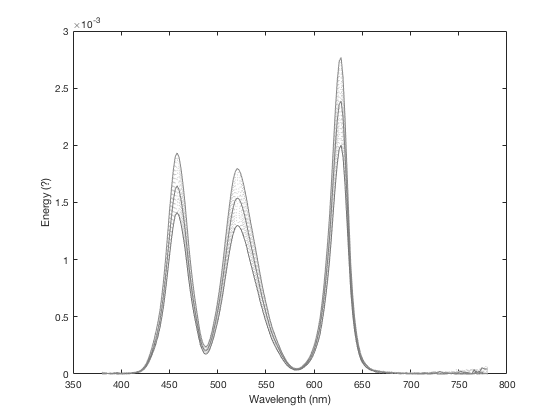

plot(horzcat(measurements.wavelengths),vertcat(measurements.SPD)',':','color', [.8 .8 .8])
xlabel('Wavelength (nm)');
ylabel('Energy (?)');
hold on;
plot(measurements(1).wavelengths,measurements(1).SPD','-','Color',RGBs(1,:));
plot(measurements(11).wavelengths,measurements(11).SPD','-','Color',RGBs(11,:));
plot(measurements(21).wavelengths,measurements(21).SPD','-','Color',RGBs(21,:));
hold off;

## Get receptors

observerAge = 32;
receptors = SSTReceptorHuman('obsAgeInYrs',observerAge);

* Setting up receptor object with parameters:
  Age [yrs]:			32
  Pupil diameter [mm]:		3.00
  Field size [deg]:		10.00
  Including penumbral cones?:	False



## Calculate receptor contrasts

receptorContrasts = SPDToReceptorContrast(vertcat(measurements.SPD)',receptors);
% extract contrast with middle level (11)
receptorContrasts = receptorContrasts(11,:,:);
% reshape matrix
receptorContrasts = permute(receptorContrasts,[3,2,1]);

## Calculate postreceptoral contrasts

LMS = sum(receptorContrasts(1:3,:),1)/3;
LminusM = diff(receptorContrasts(1:2,:),1);

## Plot

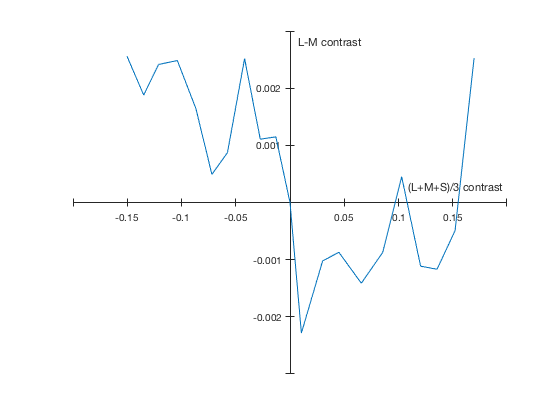

plotPostreceptoralContrasts(LMS,LminusM);